## Problem 4

Consider a continuous random variable X that has an M -shaped probability density function (PDF)

$P_X$(·) as follows:

$P_X(x) := 0 
$ for |x| > 1, and

$P_X(x) := |x|
$ for $x\in [-1,1]$.

Consider independent continuous random variables {$X_i : i
$ = 1, 2, · · · , ∞} with PDFs identical to that of X .

Define random variables $Y_N$:= (1/N)  $\sum_{i=1}^N X_i$. for N =  1, 2, · · · , ∞, which have associated distributions $P_{Y_N}(.)$.

### Part 1 [5 points]

Write code to generate independent draws from $P_X$ (·) . Submit this code.

rng(1); % If you remove the seed then x would be independent draws from the P_x
u = rand;
x = invCDF(u) % This function takes uniform random variable and given random variable with given PDF

x = -0.4074

### Part 2 [5 points: 2 + 3]

Show plots of (i) the histogram (with 200 bins) and (ii) cumulative distribution function (CDF), both using M := $10^5$ draws from the PDF $P_X$ (·) .

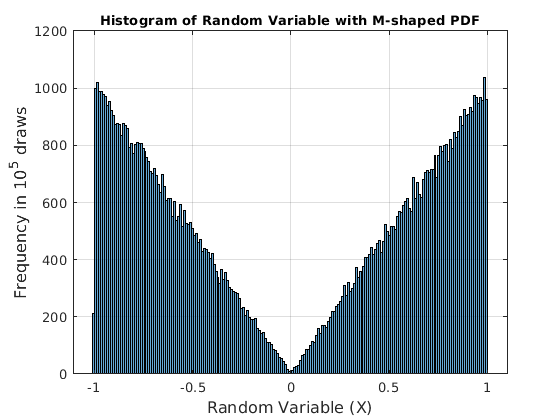

rng(1)
M = 10^5;
uM = rand(1,M); % To plot the histogram M uniform random numbers were generated
xM = invCDF(uM); % This  gave and array of M 'M-shaped' random variables

%(i)
histogram(xM,200)
grid on;
ylabel('Frequency in 10^5 draws', 'FontSize', 12);
xlabel('Random Variable (X)', 'FontSize', 12);
title('Histogram of Random Variable with M-shaped PDF', 'FontSize', 10);


%(ii)
fplot(@(x) CDF(x)) % fplot takes function (here our CDF) and plots it

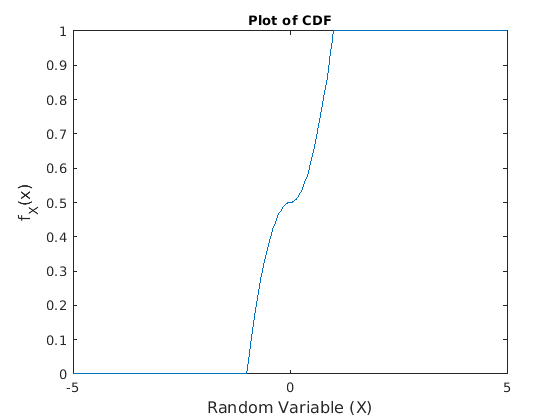

ylabel('f_X(x)', 'FontSize',12);
xlabel('Random Variable (X)','FontSize',12);
title('Plot of CDF', 'FontSize', 10);

### Part 3 [8 points]

Use the code written in the previous sub-question to write code to generate independent draws from $P_{Y_N}(.)$. Submit this code.

rng(1)
N = 100; % N has been take 100 arbitrarily
u = rand(1,N);
Yn = sum(invCDF(u))/N % average of N draws from P_X

Yn = -0.0265

### Part 4 [7 points: 3 + 4]

Show plots (separately) of histograms using $10^4$ draws from each of the PDFs $P_{Y_N}(.)$ for N =2, 4, 8, 16, 32, 64 .

Show plots, on the same graph, of all the CDFs associated with Y N for N = 1, 2, 4, 8, 16, 32, 64 ,computed using 10 4 draws from each$P_{Y_N}(.)$. Plot each CDF curve using a different color. You may use the cdfplot(.) function in Matlab.

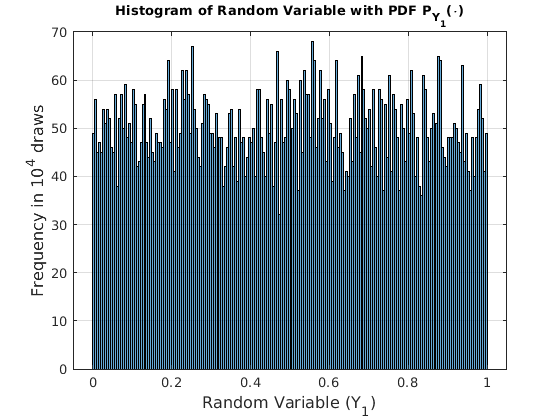

rng(1)
M = 10^4;

%(i)
Yn = []; % would be appended to make M 
for i = 1:7 % loop over various N = 2^(i-1)
    N = 2^(i-1);
    u = rand(M,N); % M x N matrix of uniform random variables
    Yn = [Yn sum(u,2)/N]; % each column contains M draws from P_Y for different values of N in each column
end

% Histogram for each column i.e, for each value of N are made separately
histogram(Yn(:,1),200);
grid on;
ylabel('Frequency in 10^4 draws', 'FontSize', 12);
xlabel('Random Variable (Y_1)', 'FontSize', 12);
title('Histogram of Random Variable with PDF P_{Y_1}(\cdot)', 'FontSize', 10);

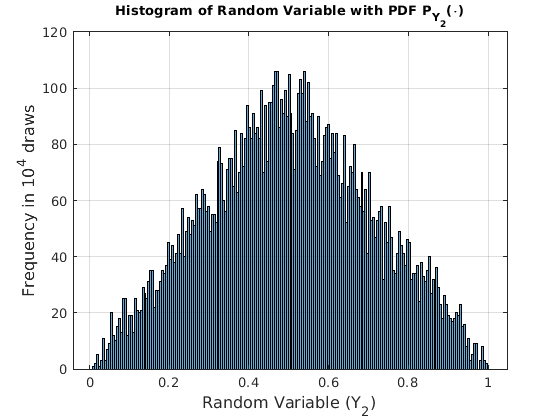


histogram(Yn(:,2),200);
grid on;
ylabel('Frequency in 10^4 draws', 'FontSize', 12);
xlabel('Random Variable (Y_2)', 'FontSize', 12);
title('Histogram of Random Variable with PDF P_{Y_2}(\cdot)', 'FontSize', 10);

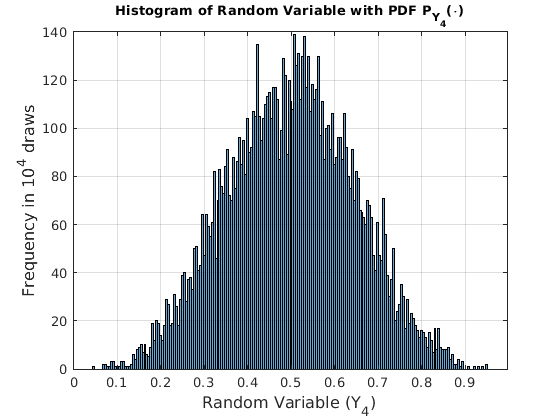


histogram(Yn(:,3),200);
grid on;
ylabel('Frequency in 10^4 draws', 'FontSize', 12);
xlabel('Random Variable (Y_4)', 'FontSize', 12);
title('Histogram of Random Variable with PDF P_{Y_4}(\cdot)', 'FontSize', 10);

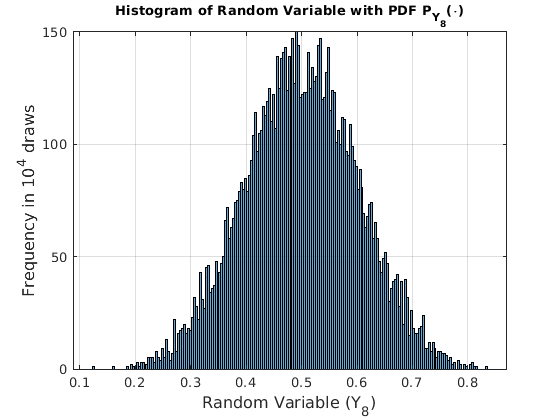


histogram(Yn(:,4),200);
grid on;
ylabel('Frequency in 10^4 draws', 'FontSize', 12);
xlabel('Random Variable (Y_8)', 'FontSize', 12);
title('Histogram of Random Variable with PDF P_{Y_8}(\cdot)', 'FontSize', 10);

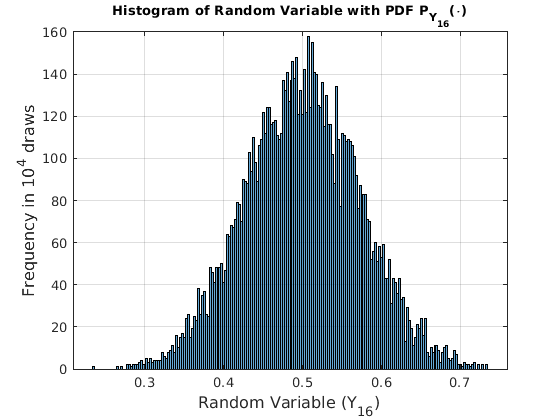


histogram(Yn(:,5),200);
grid on;
ylabel('Frequency in 10^4 draws', 'FontSize', 12);
xlabel('Random Variable (Y_{16})', 'FontSize', 12);
title('Histogram of Random Variable with PDF P_{Y_{16}}(\cdot)', 'FontSize', 10);

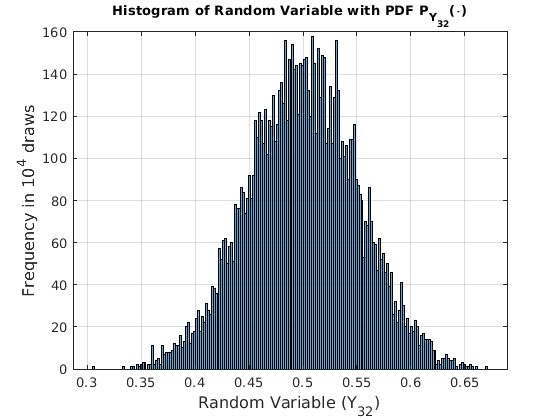


histogram(Yn(:,6),200);
grid on;
ylabel('Frequency in 10^4 draws', 'FontSize', 12);
xlabel('Random Variable (Y_{32})', 'FontSize', 12);
title('Histogram of Random Variable with PDF P_{Y_{32}}(\cdot)', 'FontSize', 10);

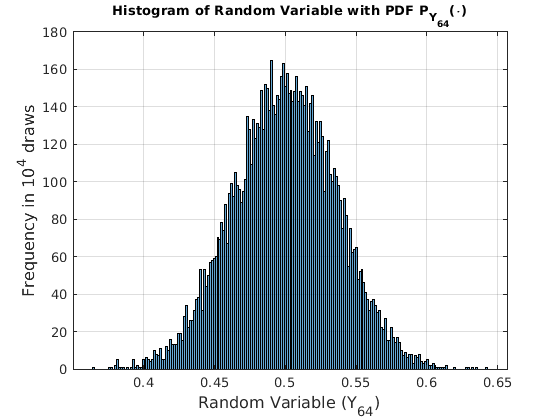


histogram(Yn(:,7),200);
grid on;
ylabel('Frequency in 10^4 draws', 'FontSize', 12);
xlabel('Random Variable (Y_{64})', 'FontSize', 12);
title('Histogram of Random Variable with PDF P_{Y_{64}}(\cdot)', 'FontSize', 10);

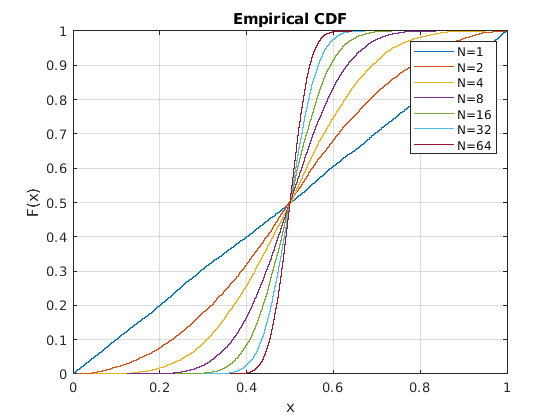


%(ii)
% cdf plots for each N in one plot
for i = 1:7
    cdfplot(Yn(:,i));
    hold on;
end
legend('N=1','N=2','N=4','N=8','N=16','N=32','N=64')

PDF function :=

function y = PDF(x)
    if abs(x) > 1
        y = 0;
    else
        y = abs(x);
    end
end

CDF function :=

function y = CDF(x)
% This CDF function has been derived in the report and have been
% implemented here
    if x < -1
        y = 0;
    elseif x >=-1 && x <= 0 
        y = (1-x^2)/2;
    elseif x >=0 && x <= 1
        y = (1+x^2)/2;
    else
        y = 1;
    end
end

Invese-CDF function :=

function y = invCDF(x)
    y(x < 0.5) = -sqrt(1-2*x(x < 0.5));
    y(x >= 0.5) = sqrt(2*x(x >= 0.5)-1);
end